# Semantic Segmentation of Multispectral Images Using Deep Learning

This example shows how to train a U-Net convolutional neural network to perform semantic segmentation of a multispectral image with seven channels: three color channels, three near-infrared channels, and a mask.

The example shows how to train a U-Net network and also provides a pretrained U-Net network. If you choose to train the U-Net network, use of a CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended (requires Parallel Computing Toolbox™).

## Introduction

Semantic segmentation involves labeling each pixel in an image with a class. One application of semantic segmentation is tracking deforestation, which is the change in forest cover over time. Environmental agencies track deforestation to assess and quantify the environmental and ecological health of a region.

Deep-learning-based semantic segmentation can yield a precise measurement of vegetation cover from high-resolution aerial photographs. One challenge is differentiating classes with similar visual characteristics, such as trying to classify a green pixel as grass, shrubbery, or tree. To increase classification accuracy, some data sets contain multispectral images that provide additional information about each pixel. For example, the Hamlin Beach State Park data set supplements the color images with near-infrared channels that provide a clearer separation of the classes.

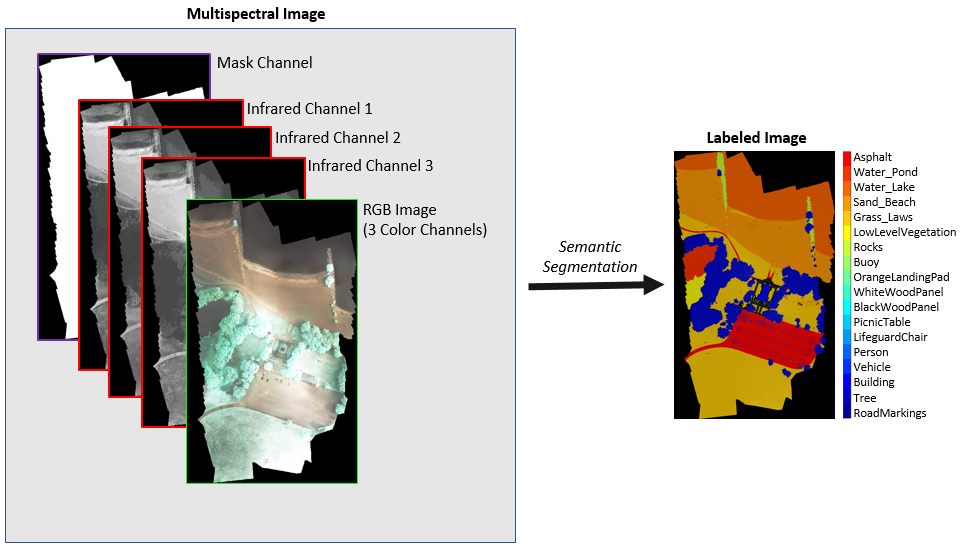

This example shows how to use deep-learning-based semantic segmentation techniques to calculate the percentage vegetation cover in a region from a set of multispectral images.

## Download Data

This example uses a high-resolution multispectral data set to train the network [1]. The image set was captured using a drone over the Hamlin Beach State Park, NY. The data contains labeled training, validation, and test sets, with 18 object class labels. The size of the data file is ~3.0 GB.

Download the MAT-file version of the data set using the `downloadHamlinBeachMSIData` helper function. This function is attached to the example as a supporting file.

imageDir = tempdir;
url = 'http://www.cis.rit.edu/~rmk6217/rit18_data.mat';
downloadHamlinBeachMSIData(url,imageDir);

This will take several minutes to download...


Error using matlab.internal.webservices.HTTPConnector/copyContentToFile (line 412)
Web service operation terminated by user while accessing URL 'http://www.cis.rit.edu/~rmk6217/rit18_data.mat'.

Error in websave (

In addition, download a pretrained version of U-Net for this dataset using the `downloadTrainedUnet` helper function (attached to the example as a supporting file). The pretrained model enables you to run the entire example without having to wait for training to complete.

trainedUnet_url = 'https://www.mathworks.com/supportfiles/vision/data/multispectralUnet.mat';
downloadTrainedUnet(trainedUnet_url,imageDir);

## Inspect Training Data

Load the data set into the workspace.

load(fullfile(imageDir,'rit18_data','rit18_data.mat'));

Examine the structure of the data.

whos train_data val_data test_data

The multispectral image data is arranged as *numChannels*-by-*width*-by-*height* arrays. However, in MATLAB®, multichannel images are arranged as *width*-by-*height*-by-*numChannels* arrays. To reshape the data so that the channels are in the third dimension, use the helper function, `switchChannelsToThirdPlane`. This function is attached to the example as a supporting file.

train_data = switchChannelsToThirdPlane(train_data);
val_data   = switchChannelsToThirdPlane(val_data);
test_data  = switchChannelsToThirdPlane(test_data);

Confirm that the data has the correct structure.

whos train_data val_data test_data

The RGB color channels are the 3rd, 2nd and 1st image channels. Display the color component of the training, validation, and test images as a montage. To make the images appear brighter on the screen, equalize their histograms by using the [`histeq`](docid:images_ref.bvhelue-1) function.

figure
montage(...
    {histeq(train_data(:,:,[3 2 1])), ...
    histeq(val_data(:,:,[3 2 1])), ...
    histeq(test_data(:,:,[3 2 1]))}, ...
    'BorderSize',10,'BackgroundColor','white')
title('RGB Component of Training Image (Left), Validation Image (Center), and Test Image (Right)')

Display the last three histogram-equalized channels of the training data as a montage. These channels correspond to the near-infrared bands and highlight different components of the image based on their heat signatures. For example, the trees near the center of the second channel image show more detail than the trees in the other two channels.

figure
montage(...
    {histeq(train_data(:,:,4)), ...
    histeq(train_data(:,:,5)), ...
    histeq(train_data(:,:,6))}, ...
    'BorderSize',10,'BackgroundColor','white')
title('IR Channels 1 (Left), 2, (Center), and 3 (Right) of Training Image')

Channel 7 is a mask that indicates the valid segmentation region. Display the mask for the training, validation, and test images.

figure
montage(...
    {train_data(:,:,7), ...
    val_data(:,:,7), ...
    test_data(:,:,7)}, ...
    'BorderSize',10,'BackgroundColor','white')
title('Mask of Training Image (Left), Validation Image (Center), and Test Image (Right)')

The labeled images contain the ground truth data for the segmentation, with each pixel assigned to one of the 18 classes. Get a list of the classes with their corresponding IDs.

disp(classes)

Create a vector of class names.

classNames = [ "RoadMarkings","Tree","Building","Vehicle","Person", ...
               "LifeguardChair","PicnicTable","BlackWoodPanel",...
               "WhiteWoodPanel","OrangeLandingPad","Buoy","Rocks",...
               "LowLevelVegetation","Grass_Lawn","Sand_Beach",...
               "Water_Lake","Water_Pond","Asphalt"]; 

Overlay the labels on the histogram-equalized RGB training image. Add a colorbar to the image.

cmap = jet(numel(classNames));
B = labeloverlay(histeq(train_data(:,:,4:6)),train_labels,'Transparency',0.8,'Colormap',cmap);

figure
title('Training Labels')
imshow(B)
N = numel(classNames);
ticks = 1/(N*2):1/N:1;
colorbar('TickLabels',cellstr(classNames),'Ticks',ticks,'TickLength',0,'TickLabelInterpreter','none');
colormap(cmap)

Save the training data as a MAT file and the training labels as a PNG file.

save('train_data.mat','train_data');
imwrite(train_labels,'train_labels.png');

## Create Random Patch Extraction Datastore for Training

Use a random patch extraction datastore to feed the training data to the network. This datastore extracts multiple corresponding random patches from an image datastore and pixel label datastore that contain ground truth images and pixel label data. Patching is a common technique to prevent running out of memory for large images and to effectively increase the amount of available training data.

Begin by storing the training images from `'train_data.mat'` in an [`imageDatastore`](docid:matlab_ref#butueui-1). Because the MAT file format is a nonstandard image format, you must use a MAT file reader to enable reading the image data. You can use the helper MAT file reader, `matReader`, that extracts the first six channels from the training data and omits the last channel containing the mask. This function is attached to the example as a supporting file.

imds = imageDatastore('train_data.mat','FileExtensions','.mat','ReadFcn',@matReader);

Create a [`pixelLabelDatastore`](docid:vision_ref#mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) to store the label patches containing the 18 labeled regions.

pixelLabelIds = 1:18;
pxds = pixelLabelDatastore('train_labels.png',classNames,pixelLabelIds);

Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) from the image datastore and the pixel label datastore. Each mini-batch contains 16 patches of size 256-by-256 pixels. One thousand mini-batches are extracted at each iteration of the epoch.

dsTrain = randomPatchExtractionDatastore(imds,pxds,[256,256],'PatchesPerImage',16000);

The random patch extraction datastore `dsTrain` provides mini-batches of data to the network at each iteration of the epoch. Preview the datastore to explore the data.

inputBatch = preview(dsTrain);
disp(inputBatch)

## Create U-Net Network Layers

This example uses a variation of the U-Net network. In U-Net, the initial series of convolutional layers are interspersed with max pooling layers, successively decreasing the resolution of the input image. These layers are followed by a series of convolutional layers interspersed with upsampling operators, successively increasing the resolution of the input image [2]. The name U-Net comes from the fact that the network can be drawn with a symmetric shape like the letter U.

This example modifies the U-Net to use zero-padding in the convolutions, so that the input and the output to the convolutions have the same size. Use the helper function, `createUnet`, to create a U-Net with a few preselected hyperparameters. This function is attached as a supporting file to the example.

inputTileSize = [256,256,6];
lgraph = createUnet(inputTileSize);
disp(lgraph.Layers)

## Select Training Options

Train the network using stochastic gradient descent with momentum (SGDM) optimization. Specify the hyperparameter settings for SDGM by using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function.

Training a deep network is time-consuming. Accelerate the training by specifying a high learning rate. However, this can cause the gradients of the network to explode or grow uncontrollably, preventing the network from training successfully. To keep the gradients in a meaningful range, enable gradient clipping by specifying `'GradientThreshold'` as `0.05`, and specify `'GradientThresholdMethod'` to use the L2-norm of the gradients.

initialLearningRate = 0.05;
maxEpochs = 150;
minibatchSize = 16;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate, ...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...    
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05, ...
    'Plots','training-progress', ...
    'VerboseFrequency',20);

## Train the Network

After configuring the training options and the random patch extraction datastore, train the U-Net network by using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) function. To train the network, set the `doTraining` parameter in the following code to `true`. A CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended for training.

If you keep the `doTraining` parameter in the following code as `false`, then the example returns a pretrained U-Net network.

*Note: Training takes about 20 hours on an NVIDIA™ Titan X and can take even longer depending on your GPU hardware.*

doTraining = false; 
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    save(['multispectralUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
else 
    load(fullfile(imageDir,'trainedUnet','multispectralUnet.mat'));
end

You can now use the U-Net to semantically segment the multispectral image.

## Predict Results on Test Data

To perform the forward pass on the trained network, use the helper function, `segmentImage`, with the validation data set. This function is attached to the example as a supporting file. `segmentImage` performs segmentation on image patches using the [`semanticseg`](docid:vision_ref.mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) function.

predictPatchSize = [1024 1024];
segmentedImage = segmentImage(val_data,net,predictPatchSize);

To extract only the valid portion of the segmentation, multiply the segmented image by the mask channel of the validation data.

segmentedImage = uint8(val_data(:,:,7)~=0) .* segmentedImage;

figure
imshow(segmentedImage,[])
title('Segmented Image')

The output of semantic segmentation is noisy. Perform post image processing to remove noise and stray pixels. Use the [`medfilt2`](docid:images_ref.bupa05x-1) function to remove salt-and-pepper noise from the segmentation. Visualize the segmented image with the noise removed.

segmentedImage = medfilt2(segmentedImage,[7,7]);
imshow(segmentedImage,[]);
title('Segmented Image  with Noise Removed')

Overlay the segmented image on the histogram-equalized RGB validation image.

B = labeloverlay(histeq(val_data(:,:,[3 2 1])),segmentedImage,'Transparency',0.8,'Colormap',cmap);

figure
imshow(B)
title('Labeled Validation Image')
colorbar('TickLabels',cellstr(classNames),'Ticks',ticks,'TickLength',0,'TickLabelInterpreter','none');
colormap(cmap)

Save the segmented image and ground truth labels as PNG files. These will be used to compute accuracy metrics.

imwrite(segmentedImage,'results.png');
imwrite(val_labels,'gtruth.png');

## Quantify Segmentation Accuracy

Create a [`pixelLabelDatastore`](docid:vision_ref#mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) for the segmentation results and the ground truth labels.

pxdsResults = pixelLabelDatastore('results.png',classNames,pixelLabelIds);
pxdsTruth = pixelLabelDatastore('gtruth.png',classNames,pixelLabelIds);

Measure the global accuracy of the semantic segmentation by using the [`evaluateSemanticSegmentation`](docid:vision_ref.mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) function.

ssm = evaluateSemanticSegmentation(pxdsResults,pxdsTruth,'Metrics','global-accuracy');

The global accuracy score indicates that just over 90% of the pixels are classified correctly.

## Calculate Extent of Vegetation Cover

The final goal of this example is to calculate the extent of vegetation cover in the multispectral image. 

Find the number of pixels labeled vegetation. The label IDs 2 ("Trees"), 13 ("LowLevelVegetation"), and 14 ("Grass_Lawn") are the vegetation classes. Also find the total number of valid pixels by summing the pixels in the ROI of the mask image.

vegetationClassIds = uint8([2,13,14]);
vegetationPixels = ismember(segmentedImage(:),vegetationClassIds);
validPixels = (segmentedImage~=0);

numVegetationPixels = sum(vegetationPixels(:));
numValidPixels = sum(validPixels(:));

Calculate the percentage of vegetation cover by dividing the number of vegetation pixels by the number of valid pixels.

percentVegetationCover = (numVegetationPixels/numValidPixels)*100;
fprintf('The percentage of vegetation cover is %3.2f%%.',percentVegetationCover);

## Summary

This example shows how to create and train a U-Net network for semantic segmentation of a seven-channel multispectral image. These are the steps to train the network:

- Download and reshape the training data.

- Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) to feed training data to the network.

- Define the layers of the U-Net network.

- Specify training options.

- Train the network using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) function.

After training the U-Net network or loading a pretrained U-Net network, the example performs semantic segmentation of the validation data and measures the segmentation accuracy.

## References

[1] Kemker, R., C. Salvaggio, and C. Kanan. "High-Resolution Multispectral Dataset for Semantic Segmentation." CoRR, abs/1703.01918. 2017.

[2] Ronneberger, O., P. Fischer, and T. Brox. "U-Net: Convolutional Networks for Biomedical Image Segmentation." CoRR, abs/1505.04597. 2015.

*Copyright 2018 The MathWorks, Inc.*